# Brain plots

Zizhuang Miao

This script can be used to create all brain maps in figures in the paper. NOTE: to achieve all customized functions (e.g., `'use_vertices_range'`), use the forked branch of the CanlabCore repository (https://github.com/Zizhuang-Miao/CanlabCore).

% Define parameters
% colormaps
nvals = 297;
pos_cm = colormap_tor([1 0 0], [1 1 1], [.98, .1, .002], ...
    [.94, .3, .008], [.92, 0.5, 0.008], [.9 .6 .1], ...
    [.92, .7, .008], [.94, .8, .005], [1 1 0], [1 1 .5], 'n', nvals); 
neg_cm = colormap_tor([0 0.8 0.8], [0 0 1], 'n', nvals);   
% graybuffer
g = 0;
% handles for four cortical surfaces and subcortical blobs
wh_handles = [1 4 7 10];
other_handles = [2 3 5 6 8 9 11 12];
% directory for all t maps
dataDir = '...\brain_maps\';

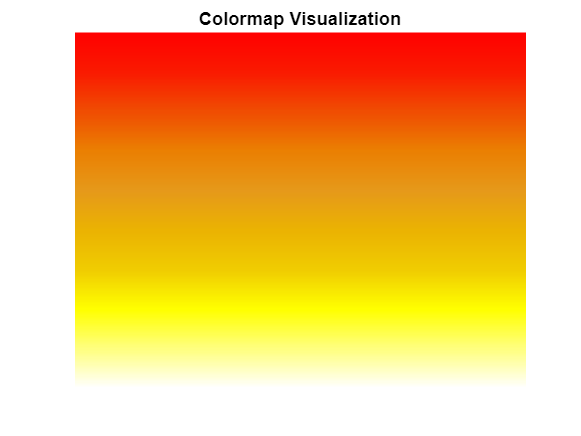

gradientImage = reshape(pos_cm, [nvals, 1, 3]);
gradientImage = repmat(gradientImage, [1, 3, 1]); % Repeat vertically

% Display the image
figure;
image(gradientImage);
axis off;
title('Colormap Visualization');

#### Example t maps -- Social interactions (Figure 3)

social_audio = remove_empty(fmri_data([dataDir, 't_social_only_audio.nii']));

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore_fork\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
iimg_get_data: loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.048221 seconds.
Number of unique values in dataset: 79773  Bit rate: 16.28 bits


social_text = remove_empty(fmri_data([dataDir, 't_social_only_text.nii']));

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore_fork\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
iimg_get_data: loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.021898 seconds.
Number of unique values in dataset: 61170  Bit rate: 15.90 bits


social_conj = remove_empty(fmri_data([dataDir, 't_social_only_conjunction.nii']));

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore_fork\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
iimg_get_data: loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.016706 seconds.
Number of unique values in dataset: 42517  Bit rate: 15.38 bits


thresh = min(abs(social_audio.dat)) / 2    % threshold for plotting vertices

thresh = single
1.5260

figure;
handles = addbrain('foursurfaces_hcp');
set(handles(1), 'Visible', 'on', 'tag', 'surface right')
set(handles(4), 'Visible', 'on', 'tag', 'surface right')
set(handles(7), 'Visible', 'on', 'tag', 'surface left')
set(handles(10), 'Visible', 'on', 'tag', 'surface left')
surface(social_conj, 'surface_handles', handles(wh_handles), ...
    'sourcespace', 'MNI152NLin2009cAsym', 'targetsurface', 'fsLR_32k', ...
    'pos_colormap', pos_cm, 'neg_colormap', neg_cm, ...
    'graybuffer', g, 'pos_min', thresh, 'neg_max', -thresh, ...
    'use_predefined_cmap', 'use_vertices_range', 'disp_vertices_range');

   -7.5576   10.8125



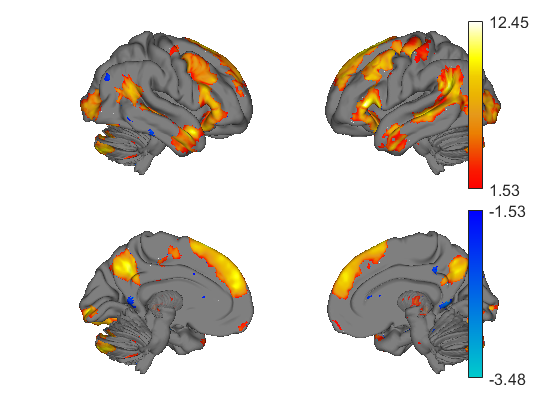

surface(social_conj, 'surface_handles', handles(other_handles),...
    'pos_colormap', pos_cm, 'neg_colormap', neg_cm, ...
    'graybuffer', g, 'pos_min', thresh, 'neg_max', -thresh, ...
    'use_vertices_range', 'use_predefined_cmap');

figure;
handles = addbrain('foursurfaces_hcp');
set(handles(1), 'Visible', 'on', 'tag', 'surface right')
set(handles(4), 'Visible', 'on', 'tag', 'surface right')
set(handles(7), 'Visible', 'on', 'tag', 'surface left')
set(handles(10), 'Visible', 'on', 'tag', 'surface left')
surface(social_conj, 'surface_handles', handles(wh_handles), ...
    'sourcespace', 'MNI152NLin2009cAsym', 'targetsurface', 'fsLR_32k', ...
    'pos_colormap', pos_cm, 'neg_colormap', neg_cm, ...
    'graybuffer', g, 'pos_min', thresh, 'neg_max', -thresh, ...
    'use_predefined_cmap', 'use_vertices_range', 'disp_vertices_range');

   -7.5576   10.8125



surface(social_conj, 'surface_handles', handles(other_handles),...
    'pos_colormap', pos_cm, 'neg_colormap', neg_cm, ...
    'graybuffer', g, 'pos_min', thresh, 'neg_max', -thresh, ...
    'use_vertices_range', 'use_predefined_cmap');

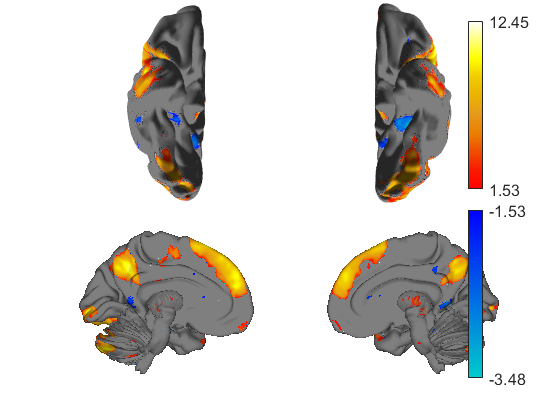

ax = findall(gcf, 'Type', 'axes');

set(handles(2), 'Visible', 'off')
set(handles(3), 'Visible', 'off')
view(ax(6), 180, -90)
camlight(ax(6), 180, -90)
camlight(ax(6), 180, -90)

set(handles(8), 'Visible', 'off')
set(handles(9), 'Visible', 'off')
view(ax(8), -180, -90)
camlight(ax(8), -180, -90)
camlight(ax(8), -180, -90)

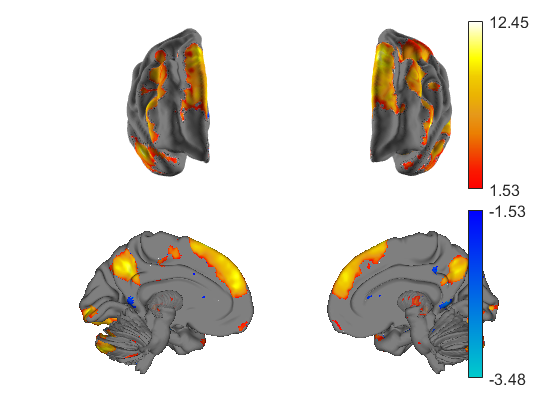

view(ax(8), 175, 10)
camlight(ax(8), 140, 50)
camlight(ax(8), 90, 10)

view(ax(6), -175, 10)
camlight(ax(6), -140, 50)
camlight(ax(6), -90, 10)

#### Bayes Factor maps (Figure 6)

dataDir = '...\brain_maps\';
bf_audio = fmri_data([dataDir, 'BFsigmap_audio_zero.nii'], which('brainmask.nii'));

iimg_get_data: loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1409312 bytes
Loading image number:     1
Elapsed time is 0.018829 seconds.
Number of unique values in dataset: 4  Bit rate: 2.00 bits


bf_text = fmri_data([dataDir, 'BFsigmap_text_zero.nii'], which('brainmask.nii'));

iimg_get_data: loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1409312 bytes
Loading image number:     1
Elapsed time is 0.017574 seconds.
Number of unique values in dataset: 4  Bit rate: 2.00 bits


bf_conj = fmri_data([dataDir, 'BFsigmap_conj_zero.nii'], which('brainmask.nii'));

iimg_get_data: loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1409312 bytes
Loading image number:     1
Elapsed time is 0.019005 seconds.
Number of unique values in dataset: 4  Bit rate: 2.00 bits


bf_cmap = [255 150 100; 100 220 255; 50 210 25]/255;    % colormap for BF map
wh_handles = [1 4 7 10];
other_handles = [2 3 5 6 8 9 11 12];

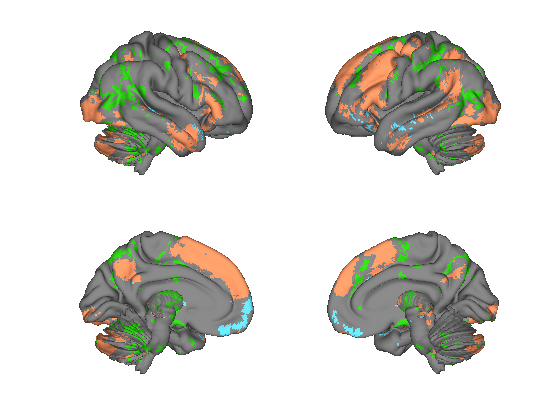

figure;
handles = addbrain('foursurfaces_hcp');
set(handles(1), 'Visible', 'on', 'tag', 'surface right')
set(handles(4), 'Visible', 'on', 'tag', 'surface right')
set(handles(7), 'Visible', 'on', 'tag', 'surface left')
set(handles(10), 'Visible', 'on', 'tag', 'surface left')
surface(bf_audio, 'surface_handles', handles(wh_handles), 'nolegend', ...
    'sourcespace', 'MNI152NLin2009cAsym', 'targetsurface', 'fsLR_32k', ...
     'indexmap', 'colormap', bf_cmap);
surface(bf_audio, 'surface_handles', handles(other_handles), 'nolegend', ...
     'indexmap', 'colormap', bf_cmap);

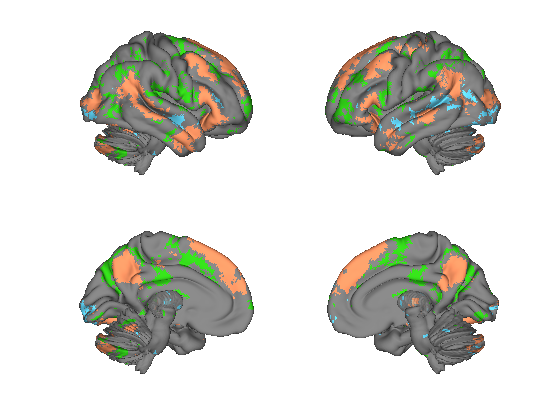

figure;
handles = addbrain('foursurfaces_hcp');
set(handles(1), 'Visible', 'on', 'tag', 'surface right')
set(handles(4), 'Visible', 'on', 'tag', 'surface right')
set(handles(7), 'Visible', 'on', 'tag', 'surface left')
set(handles(10), 'Visible', 'on', 'tag', 'surface left')
surface(bf_text, 'surface_handles', handles(wh_handles), 'nolegend', ...
    'sourcespace', 'MNI152NLin2009cAsym', 'targetsurface', 'fsLR_32k', ...
     'indexmap', 'colormap', bf_cmap);
surface(bf_text, 'surface_handles', handles(other_handles), 'nolegend', ...
     'indexmap', 'colormap', bf_cmap);

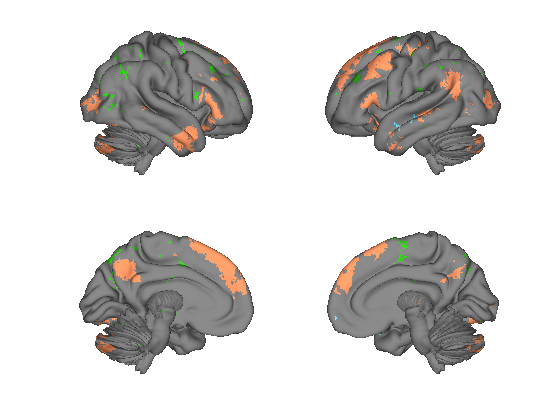

figure;
handles = addbrain('foursurfaces_hcp');
set(handles(1), 'Visible', 'on', 'tag', 'surface right')
set(handles(4), 'Visible', 'on', 'tag', 'surface right')
set(handles(7), 'Visible', 'on', 'tag', 'surface left')
set(handles(10), 'Visible', 'on', 'tag', 'surface left')
surface(bf_conj, 'surface_handles', handles(wh_handles), 'nolegend', ...
    'sourcespace', 'MNI152NLin2009cAsym', 'targetsurface', 'fsLR_32k', ...
     'indexmap', 'colormap', bf_cmap);
surface(bf_conj, 'surface_handles', handles(other_handles), 'nolegend', ...
     'indexmap', 'colormap', bf_cmap);